# The mass matrix

Mass matrices come into play when a problem of the follwoing type is to be solved:

Let $\Omega \in \mathbf{R}^2$ be a domain with $\partial \Omega = \Gamma_1 \cup \Gamma_2, \ \Gamma_1^{\circ} \cap \Gamma_2^{\circ} = \emptyset$. Further let $f :\Omega \to \mathbf{R}$, $g:\Gamma_1 \to \mathbf{R}$, $h:\Gamma_2 \to \mathbf{R}$ be continuous  and let $a:\Omega \to \mathbf{R}$ be continuous, bounded and differentiable mappings. We seek to find a twice continuously differentiable mapping $u: \bar{\Omega} \to \mathbf{R}$, which solves the strong form of the following partial differential equation (PDE).


$$
\nabla \cdot \left ( a \nabla u \right ) -cu = -f, \text{in} \ \Omega, \\
u_{\vert \Gamma_1} = g, \text{ on } \Gamma_1, \\
\frac{\partial u}{\partial n}{\vert_{\Gamma_2} = h, \text{ on } \Gamma_2. 

$$


In contrast to the formulation before, a contribution involving the solution itself has to be considered as well. These types of problems are also known as Helmholtz problems. As an example conider the damped scalar wave equation


$$\Delta \varphi \left ( r, t \right ) - \mu \kappa \frac{\partial \varphi}{\partial t}(r,t) = \mu \epsilon \frac{\partial^2 \varphi}{\partial t^2}(r,t).$$


Assuming the function $\varphi$ to be time harmonic, i.e., $\varphi(r,t) = \varphi(r) e^{-j\omega t}$ and considering fitting boundary condtions above equation can be rewritten as


$$\Delta \varphi \left ( r\right ) +\underbrace{\left (  j \omega \mu \kappa + \omega^2 \mu \epsilon \right )} \limits_{c:=}  \varphi(r) = 0.$$


We proceed by appling the Galerkin ansatz just like before, that is, we switch to a finite dimensional vectorspace $V$ with basis functions $\lbrace \phi_k \rbrace_{k=1, \ldots, n}$, apply the boundary condtions to Green's formula and end up with


$$\sum \limits_{k=1}^n u_k \langle \nabla \phi_k, \nabla \phi_l \rangle_{\Omega} -  \sum \limits_{k=1}^n u_k \langle c  \phi_k,  \phi_l \rangle_{\Omega}=  \langle h, \phi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n.$$


Which, consequently can be understood as a linear system of equations


$$C u  -  M^c u = b_{\text{boundary}},$$


where $C$denotes the stiffness matrix, and is conputed just like we did it before, the matrix $M^c$ is the mass matrix, depending on the material parameter $c$. Let's see how we can assamble this matrix.

# Assembling the mass matrix

The global mass matrix can be assembled similar to the stifness matrix by computing the mass matrix on every element, after a suitable geometry discritzation was conducted.

The local mass matrix can be determined via transformation on a reference element. So we perform the following steps:

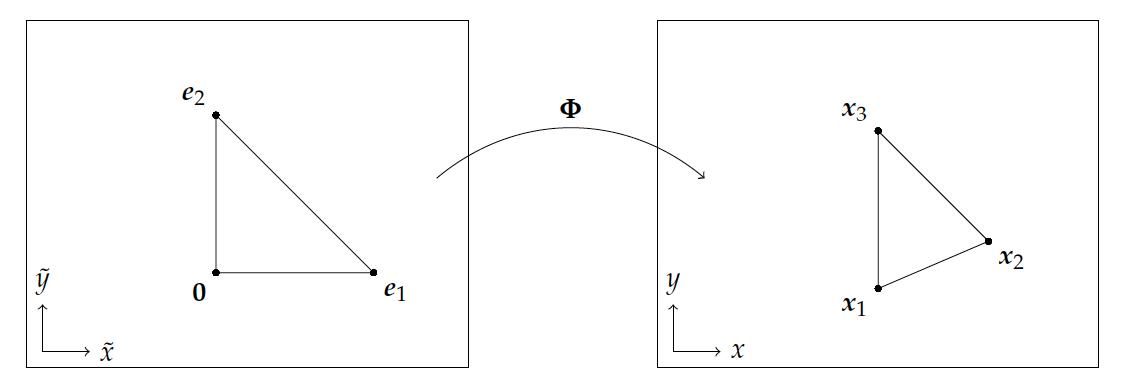

We introduce the mapping


$$\Phi_{k}\left(\tilde{x}\right)=\underbrace{\left (x_{k}^{2}-x_{k}^{1},  x_{k}^{3}-x_{k}^{1} \right )}\limits_{D_k :=} \tilde{x} +x_{k}^{1}$$


Using this mapping we can perform the computation of the integrals in the reference system. To this end we define


$$\tilde{\phi}_{i}:=\phi_{i}\circ \Phi_{k}.$$


Hence, the entries of the local mass matrix on a given triangle read


$$	m_{ij}^{k}
	=
	\int\limits_{\Omega_{k}} c\,\phi_{i}(x) \phi_{j}(x)\,d x
	=
	|\text{det}\, J_{k}| \int\limits_{\Delta} c(\Phi_{k}(\tilde{x})) \tilde{\phi}_{i}(\tilde{x}) \tilde{\phi}_{j}(\tilde{x})\,d \tilde{x}.$$


In the case of linear finite elements with guasian quadrature points at the center of the triangle the local mass matrix has this form (in 2D):


$$M^{c,k} =\frac{c\, |\text{det}\, J_{k}| }{24}\pmatrix {2 & 1 & 1 \cr 1 &2 &1 \cr 1 &1 &2}.$$


In a simple version the code would look something like:

% Omega=[0,1]x[0,1]
%

%% mesh 
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% assemble mass matrix
n=size(co,1);
m=size(elem,1);

M=sparse(n,n);

for k=1:m
    idx = elem(k,:);

    detDk = det([ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ]);

    Mloc=detDk/24*[2,1,1;1,2,1;1,1,2];

    M(idx,idx)=M(idx,idx)+Mloc;
end

And now let us compute the same in an efficient way by exploiting vectorization:

dim = size(co,2);

pipj = (ones(dim+1)+eye(dim+1))/factorial(2+dim);

%% triangle
switch dim
    case 2
        e12 = co(elem(:,2),:) - co(elem(:,1),:);
        e13 = co(elem(:,3),:) - co(elem(:,1),:);
                    
        detD = e12(:,1).*e13(:,2)-e12(:,2).*e13(:,1);

    case 3
        e12 = co(elem(:,2),:) - co(elem(:,1),:);
        e13 = co(elem(:,3),:) - co(elem(:,1),:);
        e14 = co(elem(:,4),:) - co(elem(:,1),:);
                    
        detD = dot(e12,cross(e13,e14,2),2);
end


Ns = size(pipj,1);
Nc = size(co,1);

M_fast = detD*pipj(:)';

J = repmat(1:Ns,Ns,1);
I = elem(:,J');
J = elem(:,J );

M_fast=sparse(I(:),J(:),M_fast(:),Nc,Nc);


And now let's see if we were successfull:

sum(abs(M-M_fast))

ans =    1.0e-16 *

   (1,3)       0.0087
   (1,4)       0.0694
   (1,7)       0.0347
   (1,8)       0.1214
   (1,9)       0.0087
   (1,10)      0.0347
   (1,11)      0.0694
   (1,12)      0.0607
   (1,13)      0.0694
   (1,14)      0.1214
   (1,15)      0.0954
